4.3    （牛顿法失常算例）实时脚本

由张志涌编写、修改于 2023.1。

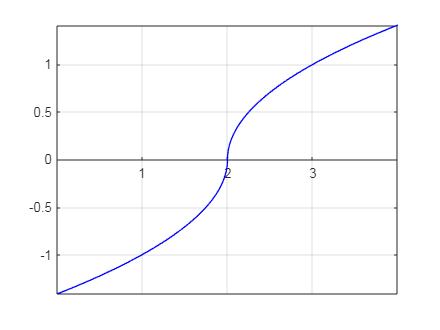

clear
syms x
a=2;
f(x)=sign(x-a)*sqrt(abs(x-a));
fh=fplot(f(x),[0,4],'Color','b','Linewidth',1);
set(gca,'XAxisLocation','origin','YAxisLocation','origin')
grid on

dfx=diff(f,x)

$$dfx(x) = 2\,\sqrt{\left|x-2\right|}\,\delta (x-2)+\frac{{\mathrm{sign}\left(x-2\right)}^{2}}{2\,\sqrt{\left|x-2\right|}}$$

dfx1=double(dfx(1))

dfx1 =    0.500000000000000


dfx3=double(dfx(3))

dfx3 =    0.500000000000000


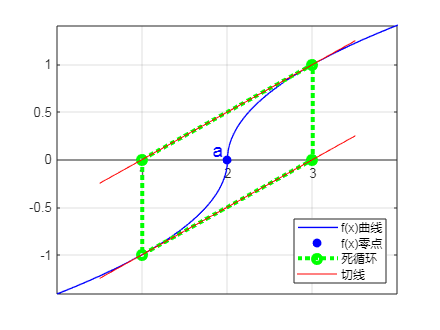

zh=line(2,0,'Marker','.','Color','b','MarkerSize',20,'Linestyle','none');
ch=line([1,1,3,3,1],[0,f(1),0,f(3),0],'Color','g','Linewidth',3,...
    'Marker','o','Linestyle',':');
text(1.95,0.1,'a','HorizontalAlignment','right','FontSize',14,'Color','b')
tt=0.5:0.1:3.5;
tan1=f(1)+dfx1*(tt-1);
th=line(tt,tan1,'Color','r','Linewidth',0.5);
tan3=f(3)+dfx3*(tt-3);
line(tt,tan3,'Color','r','Linewidth',0.5)
legend([fh,zh,ch,th],{'f(x)曲线','f(x)零点','死循环','切线'},'Location','southeast')